clear all
close all
syms R C Ep t w
netlist={'V1 1 0 Ep'
    'R1 1 2 R'
    'R2 2 4 R'
    'C1 2 0 2*C'
    'C2 1 3 C'
    'C3 3 4 C'
    'R3 3 0 R/2'};
[X name]=fspice(netlist)

** fspice 2.43  ** (c) Frederic Martinez


$$X = \begin{array}{l} \left(\begin{array}{c} \mathrm{Ep}\\ \frac{\mathrm{Ep}\,\left(C\,R\,s+1\right)}{\sigma_{1}}\\ \frac{C\,\mathrm{Ep}\,R\,s\,\left(C\,R\,s+1\right)}{\sigma_{1}}\\ \frac{\mathrm{Ep}\,\left(C^{2}\,R^{2}\,s^{2}+1\right)}{\sigma_{1}}\\ -\frac{4\,\mathrm{Ep}\,\left(R\,C^{2}\,s^{2}+C\,s\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C^{2}\,R^{2}\,s^{2}+4\,C\,R\,s+1 \end{array}$$

name = 1×5 cell array
    {'V(1)'}    {'V(2)'}    {'V(3)'}    {'V(4)'}    {'I(V1)'}


H=X(4)/X(1); %TL de la tension au noeud 4 sur TL de la tension au noeud 1
f=20; % en Hz, à faire varier 20, 170 puis 10000 Hz
e=cos(2*pi*f*t)*heaviside(t); %e(t)
E=laplace(e) %TL de e(t)

$$E = \frac{s}{s^{2}+1600\,\pi^{2}}$$

S=E*H; % TL de s(t)
st=ilaplace(S) %TL inverse de S

$$st = \begin{array}{l} \frac{2560000\,\pi^{4}\,\sigma_{2}\,C^{4}\,R^{4}-256000\,\pi^{3}\,\sigma_{4}\,C^{3}\,R^{3}-3200\,\pi^{2}\,\sigma_{2}\,C^{2}\,R^{2}+160\,\pi \,\sigma_{4}\,C\,R+\sigma_{2}}{\sigma_{1}}+\frac{25600\,C^{2}\,R^{2}\,\pi^{2}\,{\mathrm{e}}^{-\frac{2\,t}{C\,R}}\,\left(\cosh\left(\sigma_{3}\right)-\frac{\sqrt{3}\,C\,R\,\sinh\left(\sigma_{3}\right)\,\left(\frac{2}{C\,R}+\frac{4\,C\,R-6400\,C^{3}\,R^{3}\,\pi^{2}}{25600\,C^{4}\,R^{4}\,\pi^{2}}\right)}{3}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=2560000\,\pi^{4}\,C^{4}\,R^{4}+22400\,\pi^{2}\,C^{2}\,R^{2}+1\\ \sigma_{2}=\cos\left(40\,\pi \,t\right)\\ \sigma_{3}=\frac{\sqrt{3}\,t}{C\,R}\\ \sigma_{4}=\sin\left(40\,\pi \,t\right) \end{array}$$

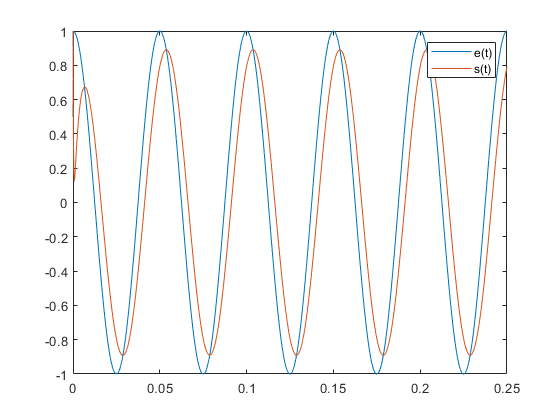

t=linspace(0, 5/f,1000); R=1e3; C=1e-6;
enum=subs(e);
snum=subs(st);
plot(t,enum, t,snum)
legend('e(t)','s(t)')

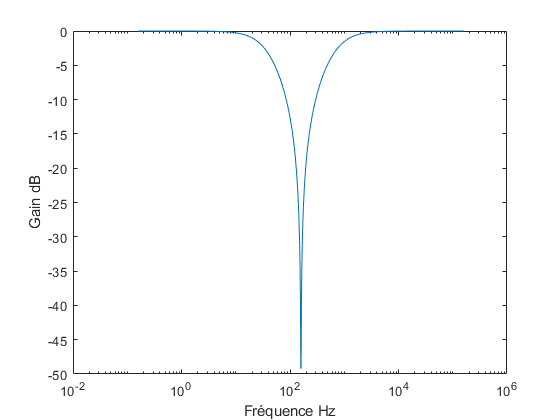

s=1j*w;
H=subs(H);
w=logspace(0,6,1000);
H=subs(H);
figure
semilogx(w/(2*pi),20*log10(abs(H)))
xlabel('Fréquence Hz')
ylabel('Gain dB')

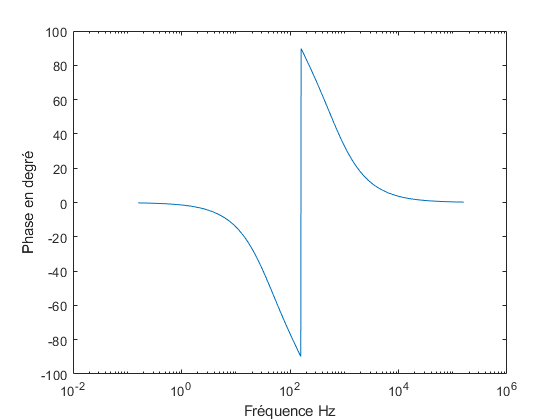

figure 
semilogx(w/(2*pi), angle(H)*180/pi)
xlabel('Fréquence Hz')
ylabel('Phase en degré')